# Poloidal field coils current controller

Except for the VS system, usually the magnetic control system of a tokamak exploits the **poloidal field (PF) coils currents as actuators**. The key idea is simple: the magnetic equilibrium is determined by the currents (which are the source terms in the GS equation), so the currents are the most natural actuator to control the equilibrium and the related quantities. However, coils are most often driven by applying *voltages*: hence, it is necessary to *control *the currents with a dedicated control loop, which will provide a reliable actuator to the others. This leads to a nested control architecture, as in the figure below

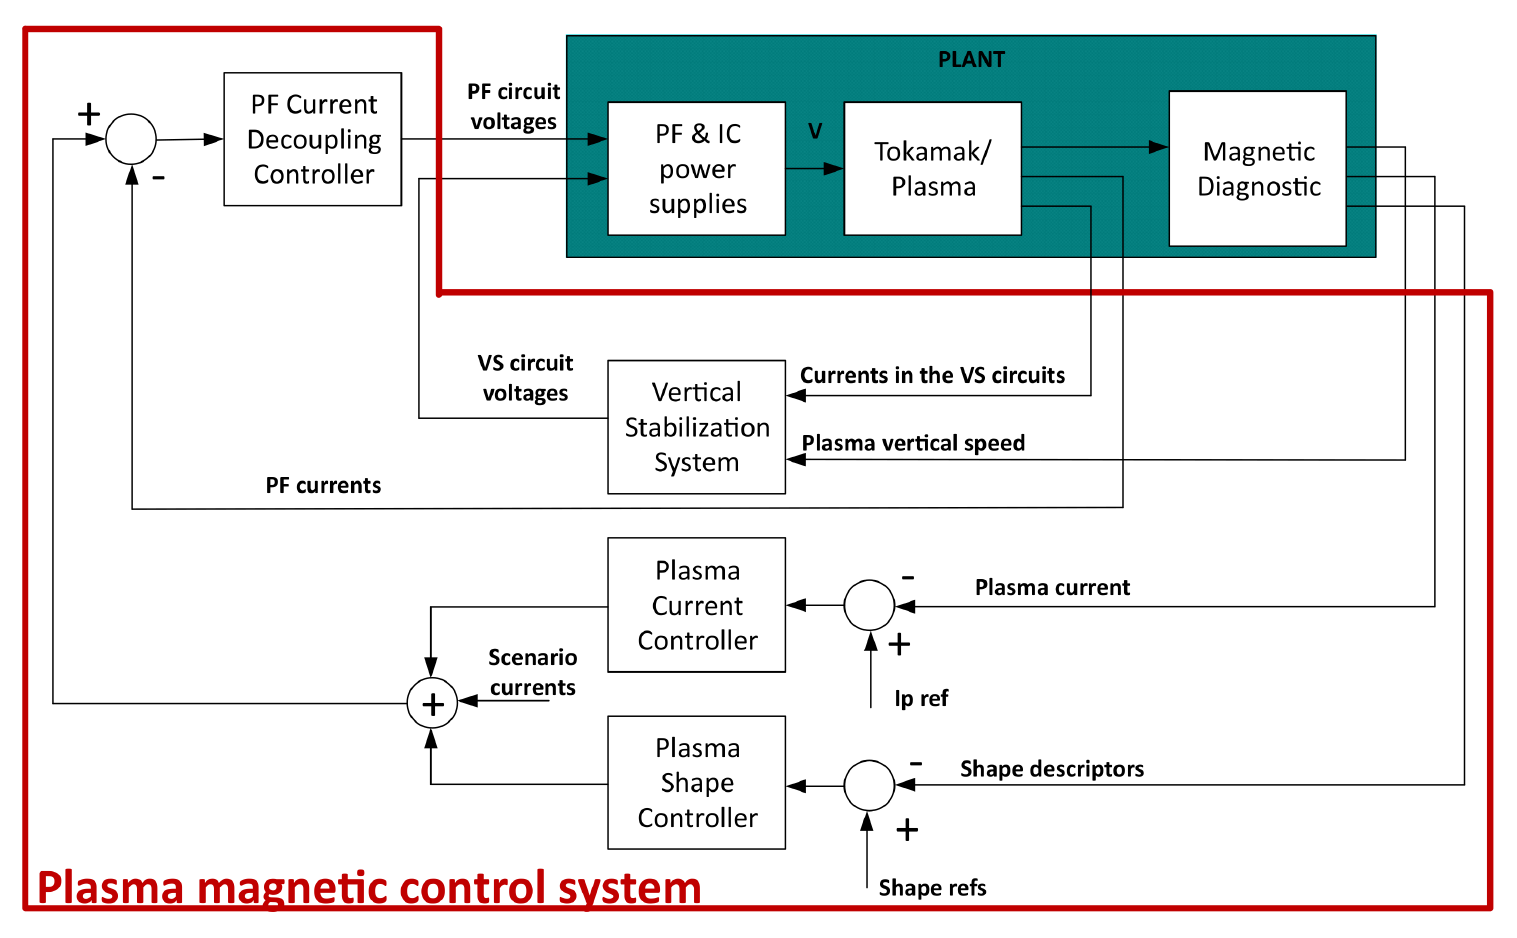

## Preliminaries

To design this controller, let's start from the circuit equation we saw in the previous exercises


$$L\dot{I}(t)+RI(t) = V(t)$$


and, first fo all, compensate the coils resistances


$$V(t)=RI(t)+V_1(t)$$


This choice turns the systems into a bunch of integrators


$$L\dot{I}(t)=V_1(t)$$


(in the case of JT-60SA, R=0 for all the PF coils, so there is no need for the resistance compensation term!) 

These integrators are *coupled* via the inductance matrix L. If this matrix is known/measurable, we can in principle assign arbitrary current dynamics by adding another control term


$$V(t)=RI(t)-L\Lambda I(t)$$


where the matrix $\Lambda$ is in general chosen as $\lambda \mathbf{I}$, $\lambda 
$ being the desired eigenvalue for the currents dynamics (with a - sign). Indeed, for each current we get


$$\frac{d}{dt}i(t)= - \lambda i(t)$$


If we want to track a reference (assume it constant for simplicity), we can set


$$V(t) = RI(t) + L \Lambda (I_{ref}-I(t))$$


to get the error dynamics


$$\frac{d}{dt} (I_{ref}-I(t)) = -\dot{I}(t)= -\Lambda (I_{ref}-I(t))$$


(of course, if the reference is slowly varying wrt $1/\lambda$ this same argument will -approximately- hold as well).

However, we have **two main problems** here

- L depends in general on the plasma configuration, which may vary during the experiment and/or be unknown

- L contains the effect of the eddy currents, which usually are not measurable

so we make the following **approximations**

- we design the controller based on the *plasmaless* model, hoping that the effect of the plasma on the L matrix is negligible

- we neglect the effect of the eddy currents, and use a reduced L matrix (the same holds for R)

## Design and validation

First, let's load our plasmaless model

addpath ./functions
addpath ./models
addpath ./data 

plasmalessName = fullfile(pwd,'models','plasmaless_FG.mat');
plasmaless = load(plasmalessName);

and extract the inductance matrix terms associated to the active currents

L = plasmaless.L(1:10,1:10); % 4 CS modules and 6 EF coils

Second, we choose an eigenvalue for our current dynamics (which must be quite faster than the expected dynamics for the external control loops)

lambda = 1/5e-2; % a time constant of 50ms looks fine

Third, we compute our decoupling/control matrix as

Kcurr = L * lambda*eye(10)

Kcurr =     5.5914    1.2277    0.1683    0.0496    0.3366    0.4705    0.8528    0.0607    0.0890    0.1781
    1.2277    5.6866    1.2340    0.1685    0.3585    0.3467    0.2541    0.1304    0.1607    0.2861
    0.1683    1.2340    5.6889    1.2280    0.3057    0.2142    0.0954    0.3424    0.2950    0.4248
    0.0496    0.1685    1.2280    5.6044    0.2217    0.1271    0.0441    1.1408    0.4859    0.5202
    0.3366    0.3585    0.3057    0.2217   10.5242    2.7680    0.6328    0.4892    0.8769    2.0176
    0.4705    0.3467    0.2142    0.1271    2.7680    9.0970    1.1993    0.2482    0.4272    0.9471
    0.8528    0.2541    0.0954    0.0441    0.6328    1.1993    6.3660    0.0734    0.1202    0.2578
    0.0607    0.1304    0.3424    1.1408    0.4892    0.2482    0.0734   12.0744    2.1407    1.7028
    0.0890    0.1607    0.2950    0.4859    0.8769    0.4272    0.1202    2.1407    7.1886    3.7815
    0.1781    0.2861    0.4248    0.5202    2.0176    0.9471    0.2578    1.7028   

pretty simple, isn't it? Then, in general we remove the smallest, negligible terms appearing in the matrix and only keep the most significant couplings between the coils

for i = 1 : size(Kcurr,1)
  idx = Kcurr(i,:)<Kcurr(i,i)*0.1; % the threshold is the 10% of each circuit's self inductance
  Kcurr(i,idx) = 0;
end

and round the numbers (for the poor guy in charge of copying them into the pcs and double-checking everything)

Kcurr = round(Kcurr,2) % two digits after the . seems right

Kcurr =     5.5900    1.2300         0         0         0         0    0.8500         0         0         0
    1.2300    5.6900    1.2300         0         0         0         0         0         0         0
         0    1.2300    5.6900    1.2300         0         0         0         0         0         0
         0         0    1.2300    5.6000         0         0         0    1.1400         0         0
         0         0         0         0   10.5200    2.7700         0         0         0    2.0200
         0         0         0         0    2.7700    9.1000    1.2000         0         0    0.9500
    0.8500         0         0         0         0    1.2000    6.3700         0         0         0
         0         0         0         0         0         0         0   12.0700    2.1400    1.7000
         0         0         0         0    0.8800         0         0    2.1400    7.1900    3.7800
         0         0         0         0    2.0200         0         0    1.7000   

Done! Let's close our loop and see what happens. For now we'll try it on the plasmaless model and verify that the dynamics is the one we expect

pm.A = -plasmaless.L\plasmaless.R;
pm.B =  plasmaless.L\eye(size(plasmaless.L));
pm.C =  plasmaless.C;
pm.D =  zeros(size(pm.C,1), size(pm.B,2)); 

then we initialize the ss objects for the plant and the controller

Inames = plasmaless.y_type(1:10,1);
Vnames = Inames;
for i=1:numel(Vnames), Vnames{i} = ['V_' Vnames{i}]; end

PF_sys = ss(pm.A, pm.B(:,1:10), pm.C(1:10,:), pm.D(1:10,1:10),...
         'inputname',Vnames,'outputname',Inames); % the first 10 inputs/outputs are the active currents

PF_contr = ss(Kcurr,'inputname',Inames,'outputname',Vnames);

compute the open and closed loop systems

PF_olsys = series(PF_contr,PF_sys,'name');
PF_clsys = feedback(PF_sys*PF_contr,eye(10));

and check the Bode plots on all the control channels

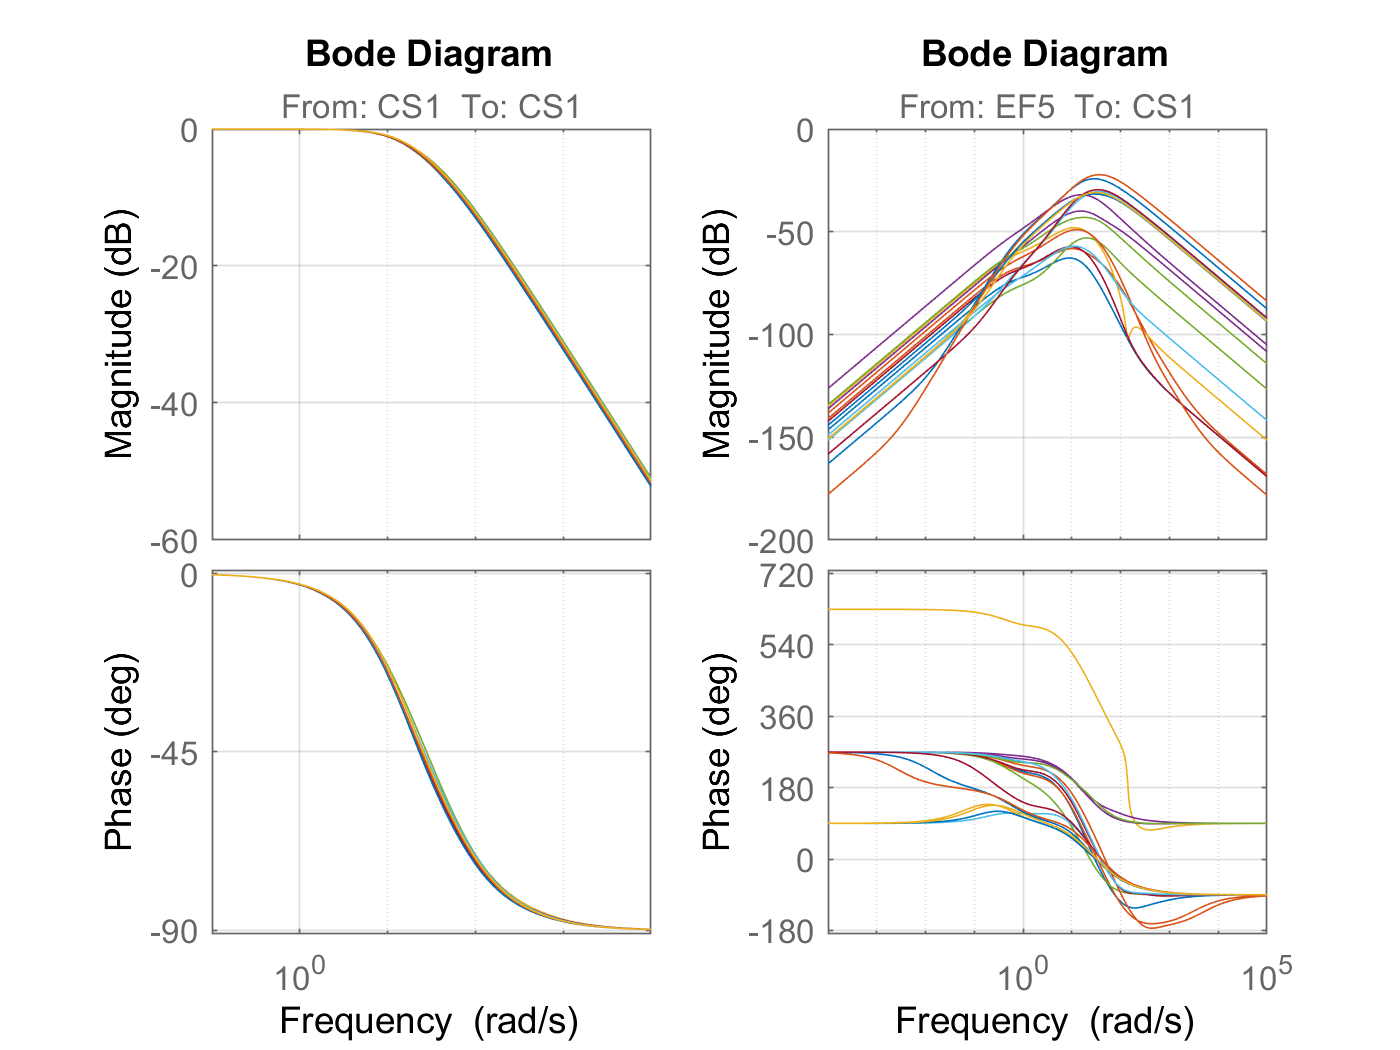

figure

% These are the on-diagonal channels (gain~1 and bandwidth~1/lambda)
 subplot(121)
 hold on
for i = 1:10
  bode(PF_clsys(i,i));
end
grid on
  
% To make the code lighter, we just pick a bunch of random off-diagonal
% channels (these should have a very small gain)
subplot(122)
hold on
for i = 1:10  
  for j = setdiff(randi(10,1,2),i)
    bode(PF_clsys(i,j)); 
  end
end
grid on

% % This is the full version (but it's quite slow)
% subplot(122)
% hold on
% for i = 1:10  
%   for j = setdiff(1:10,i)
%     bode(PF_clsys(i,j)); 
%   end
% end
% grid on

## Test with plasma

Let's try our controller on a model with plasma. First we need to load our model file (these are the same operations we have seen in the previous exercise, just repeated to make each file stand-alone)

modelName = fullfile(pwd,'models','SOF@18d66s_FG.mat'); 
model = load(modelName); 

lm.A = -model.L\model.R;
lm.B =  model.L\eye(size(model.L));
lm.C =  model.C;
lm.D =  zeros(size(lm.C,1), size(lm.B,2)); 
lm.E = -model.L\model.LE;
lm.F =  model.F;

The only difference is that we'll include the PF currents in the inputs and outputs this time

% VSU-VSL are the 11th and 12th inputs
lm.B = [lm.B(:,1:10) lm.B(:,11)-lm.B(:,12)];
lm.D = [lm.D(:,1:10) lm.D(:,11)-lm.D(:,12)];

% Identify output positions
i_out = get_y_idx(model.y_type,{'VSU','VSL','Zpl'},1);

% Re-assign C ...
C_imbalance = (lm.C(i_out(1),:)-lm.C(i_out(2),:))/2;
C_zp        =  lm.C(i_out(3),:);
lm.C = [lm.C(1:10,:); C_imbalance; C_zp]; % 1:10 -> PF currents
% ... D
D_imbalance = (lm.D(i_out(1),:)-lm.D(i_out(2),:))/2;
D_zp        =  lm.D(i_out(3),:);
lm.D = [lm.D(1:10,:); D_imbalance; D_zp];
% ... and F (just for consistency, we'll not use it!)
F_imbalance = (lm.F(i_out(1),:)-lm.F(i_out(2),:))/2;
F_zp        =  lm.F(i_out(3),:);
lm.F = [lm.F(1:10,:); F_imbalance; F_zp];

We are ready to build our ss objects...

plasma_sys = ss(lm.A,lm.B,lm.C,lm.D,...
                'inputname', [Vnames' {'VSU-VSL'}], ...
                'outputname',[Inames' {'(IVSU-IVSL)/2','Zp'}]);

VS_olsys = ss(plasma_sys.a, ...
            plasma_sys.b, ...
            [plasma_sys.c; plasma_sys.c(end,:)*plasma_sys.a], ... % Just use the ideal zp derivative for simplicity
            [plasma_sys.d; plasma_sys.c(end,:)*plasma_sys.b]);

VS_olsys.inputname  = [Vnames' {'VSU-VSL'}];
VS_olsys.outputname = [Inames' {'(IVSU-IVSL)/2','Zp','Zdot'}];

...close the VS control loop...

% K_VS_sys = ss([-0.6155 1347],'inputname',{'(IVSU-IVSL)/2','Zdot'},'outputname',{'VSU-VSL'}); % These are just the gains obtained in the previous exercise
load VS_contr.mat
VS_clsys = feedback(VS_olsys,VS_contr,'name');

... and the PF current control loop as well

PF_olsys = series(PF_contr,VS_clsys,'name');
PF_olsys = PF_olsys(1:10,1:10); % pick the PF coils

PF_clsys = feedback(PF_olsys,eye(10));

Let's see what happens if we try to track a step on some of the coils (pick 4 random and remove duplicates if any)

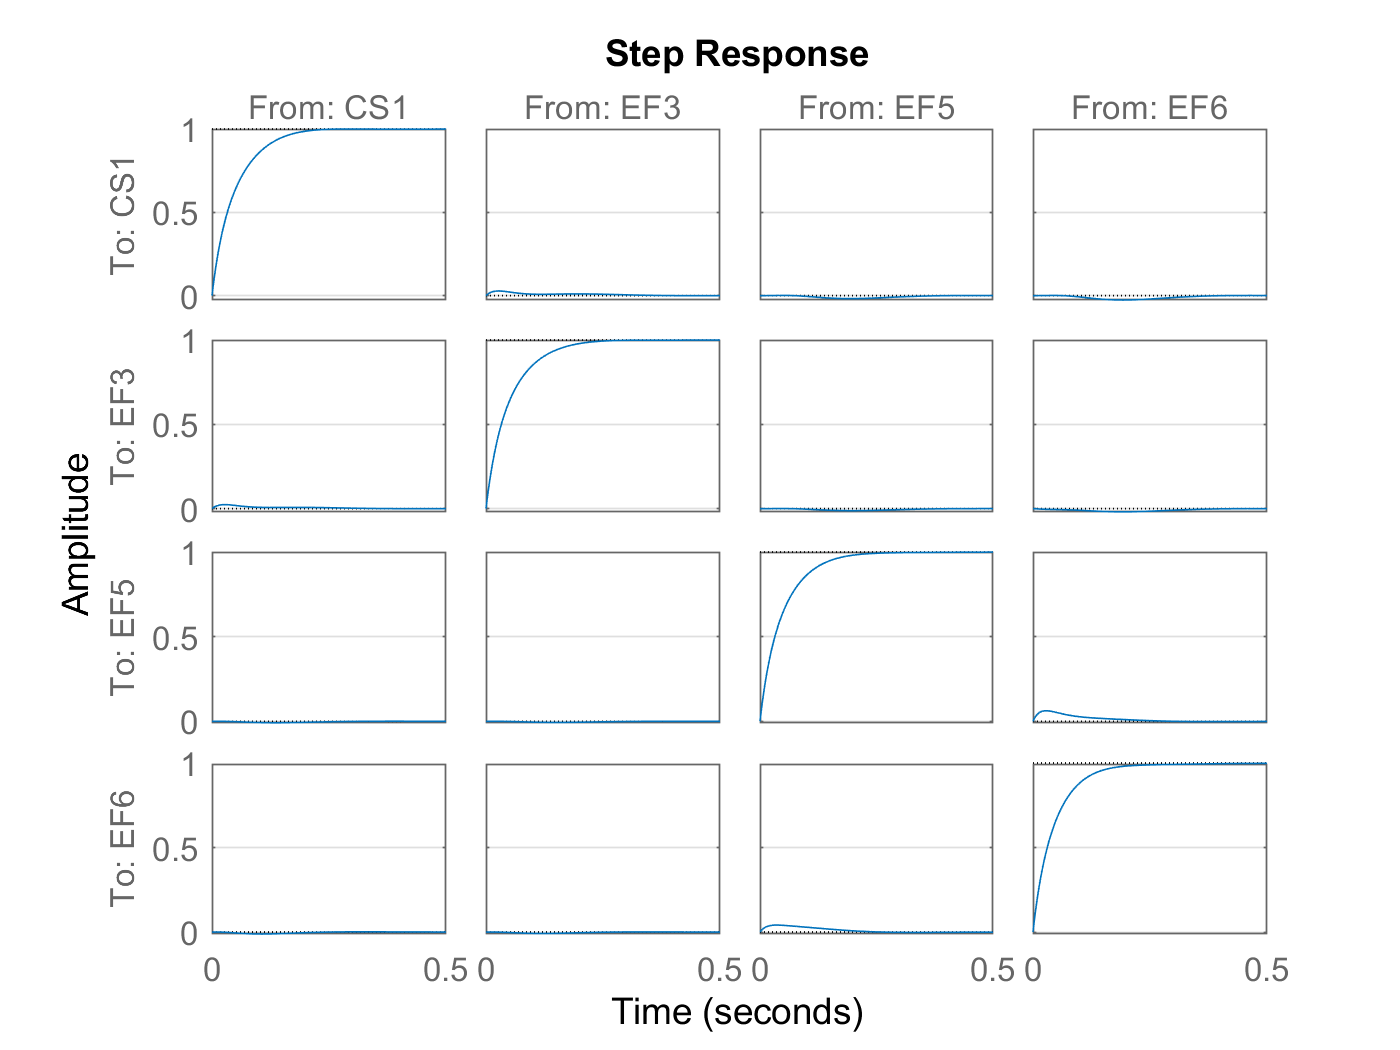

ii = randi(10,4,1);
ii = unique(ii);
figure
step(PF_clsys(ii,ii),0:1e-3:0.5)
grid on

Pretty good! Stability is preserved (phew!), the coils have very similar dynamics (as expected) and the off-diagonal terms are much smaller (which means good decoupling).

As a final remark, sometimes a dynamic controller can also be added in the loop to satisfy other control requirements (e.g. a slight overshoot can be used to achieve a faster response). However, we'll stop here for now and move to the next controller.

As before, save the controller for later use

save ./data/PF_contr PF_contr PF_clsys

## Bonus: experiments

If this controller is properly designed and implemented, it allows to greatly simplify the design of the outer control loops. 

Indeed, with the PFC current decoupler in place, we can treat the coils as simple 1st or 2nd order systems!

As an example, here we show some experimental results obtained at the EAST tokamak: the black line is the reference, the red line is the simulated behaviour of the coils with the proposed controller, the blue dashed line is the closed-loop behaviour when the controller is closed on a pure integrator and the green lines are the experimental results. The agreement with experiments is not bad at all!